# Understanding Inductances

## Introduction

We can define inducatnce of 1 H as that coil where magnetic flux of 1 weber get linked to that coil when we passes 1 A current from that coil. If it is single turn coil flux produced will be 1 weber. If it is 10 turn coil flux will be 0.1 weber.

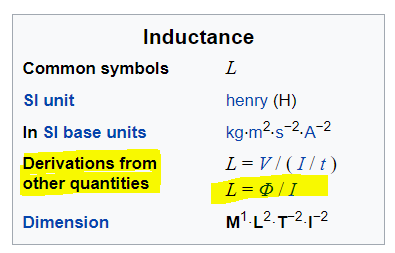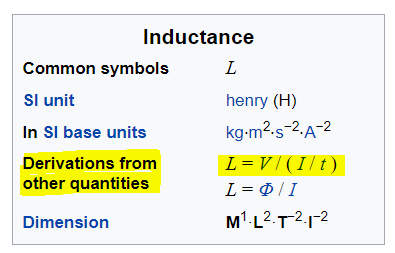

Other definition of 1 H inductance is that inductance when it supplied with 1 V, after 1 sec current through it will be 1 A. Thus when we supply with voltage of V volts after 1 sec. current will be V ampers. Thus if we supply with V volts for S sec. current will be V*S amperes. This is for 1 H inductance. Thus from the relation as 

L = V*t/I we have I = V*t/L

Thus for 400 mH inductance supplied by 60 Vdc, current after 0.08 seconds will be 60*0.08/(400*0.001) = 12 Amp.

We will check this fact using simulink-simuscape. however throughout simulation period of 0.01 seconds voltage across the inductor will be constant and that to 12 V.

Make the simscape electrical circuit as below

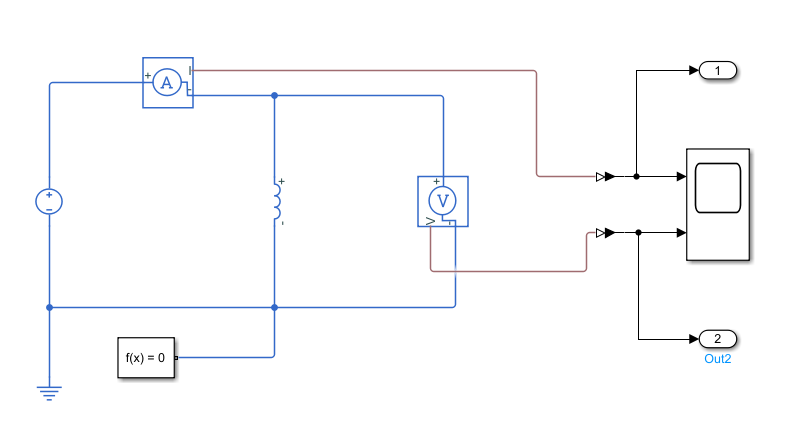

From here we may change the importent parameters of the model

#### NOTE: Simscape inducatnce model includes very small default conductance in parallel with it thus it changes value of current by very small amount.

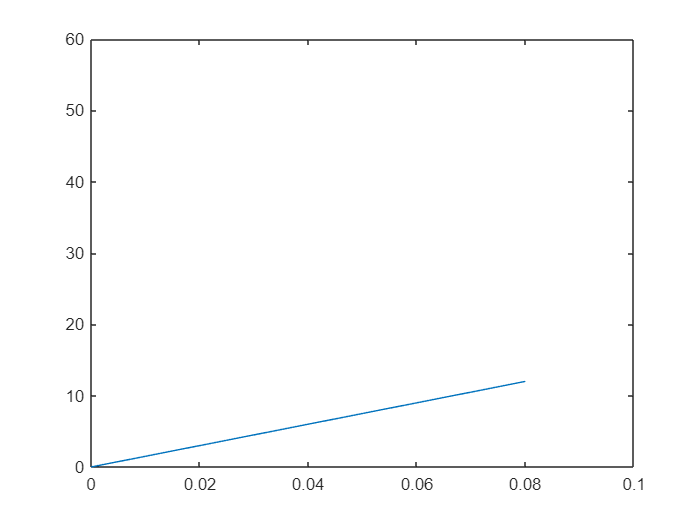

clc
clear

L = 400;
V = 60;
simulationTime = 0.08;

sim("Inductance.slx");

VOUT = ans.yout(:,2);
IOUT = ans.yout(:,1);

plot(ans.tout,IOUT);
xlim([0 0.1]);
ylim([0 60]);